# Synthesize a controller with a setteling time of 2 min. 

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
%Wref
%lowpass filter wich result in a setling time of 10 min (600 sec) .  
s=tf('s');
wref =eye(4)*(1/(120*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

## FWMM on SF

param.model.Dwz = 5*eye(4);
param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for FWMM 
Gamma is found to be: 0.589177 


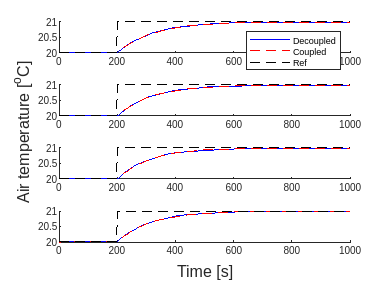

[resDeSF,resSF] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults",0,1000);

info = stepinfo(resSF.Ta(:,1),resSF.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 593.680626 


## FWMM on SOF

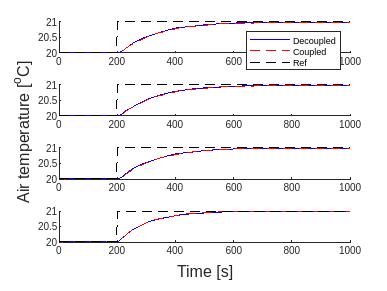

param.model.Dwz = 6.5*eye(4);

%% Run synthesis or load pre run controller.
%param = control.DesignProcedureSOF_ILMI_FWMM(param,0,{[-1,1]});
load('SOF_Performance608.mat')

[resDeSoF,resSOF] = util.SimulateStep(param,"SimulateNonlinearSOFResults",0,1000);

info = stepinfo(resSOF.Ta(:,1),resSOF.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SOF is: %f \n', (info.SettlingTime - 200));

Settling time for SOF is: 607.589600 


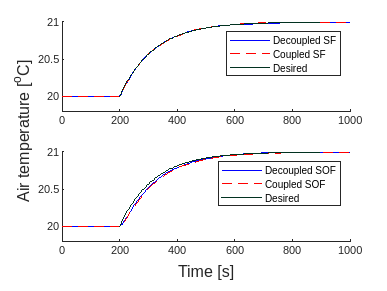


util.CompareDesired(param,'CompareDesired',resDeSF,resSF,resDeSoF,resSOF);

# Synthesize a controller with a setteling time of 2 min. 

### Initizilation

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
%Wref
%lowpass filter wich result in a setling time of 2 min (120 sec) .  
s=tf('s');
wref =eye(4)*(1/(24*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);

## FWMM on SF

param.model.Dwz = 20*eye(4);
param = control.DesignProcedureFWMM(param,0);

Evaluation of design procedure for FWMM 
Gamma is found to be: 0.591719 


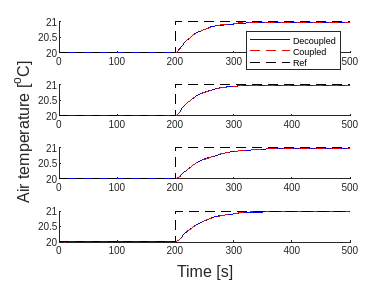

[~,res] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 164.082519 


Attempt with polytopic uncertainties

param = control.DesingProcedureFWMM_Polytopic(param,0,{[-1,1]});

Evaluation of design procedure for FWMM uncertainties
Gamma is found to be: 0.000195 


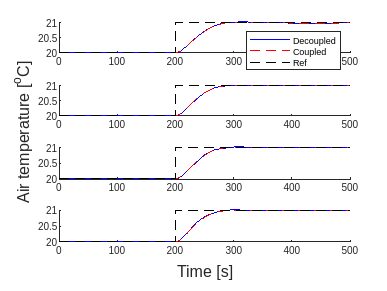

figure()
[~,res] = util.SimulateStep(param,"SimulateNonlinearStatefeedbackResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SF is: %f \n', (info.SettlingTime - 200));

Settling time for SF is: 169.023594 


## FWMM on SOF

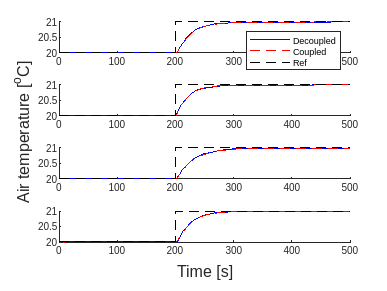

param.model.Dwz = 5*eye(4);

%% Run synthesis or load pre run controller.
%param = control.DesignProcedureSOF_ILMI_FWMM(param,0,{[-1,1]});
load("SOF_Performance2min.mat")

[~,res] = util.SimulateStep(param,"SimulateNonlinearSOFResults_2_min",0,500);

info = stepinfo(res.Ta(:,1),res.time,util.Celsius2Kelvin(21),util.Celsius2Kelvin(20),'SettlingTimeThreshold',0.007);
fprintf('Settling time for SOF is: %f \n', (info.SettlingTime - 200));

Settling time for SOF is: 120.836759 
